# Couette Flow High Fidelity Results

The Couette Flow is decribed by a fluid between two infinite walls, with one wall in motion (with a velocity U). The Navier-Stokes Equation get converted to a 1D Poisson Equation, which is analytically tractable. 


$$\frac {\partial u}{\partial t} = \nu \frac{\partial^2 u}{\partial y^2}$$
  

Boundary conditions: $u\left(0,t\right)=0,u\left(1,t\right)=U$

Initial condition: $u\left(y,0\right)=0$

The analytical solution to this equation involes separation of the solution into steady state and transient components. The steady state component is required to take the non-homogenous boundary condition, whereas the transient problem takes care of the initial condition with homogenous boundary conditions.

i.e. $u\left(y,t\right)=u_{\mathrm{ss}} \left(y\right)+u_{\mathrm{transient}} \left(y,t\right)$

Now, we can recast the problem:


$$\frac {\partial u_{transient}}{\partial t} = \nu \frac{\partial^2 (u_{ss} + u_{transient}) }{\partial y^2}$$
 

Boundary conditions: $u\left(0,t\right)=u_{\mathrm{ss}} \left(0\right)+u_{\mathrm{transient}} \left(0,t\right)=0,u\left(1,t\right)=u_{\mathrm{ss}} \left(1\right)+u_{\mathrm{transient}} \left(1,t\right)=U\;$

Initial Conditions: $u\left(y,0\right)=u_{\mathrm{ss}} \left(y\right)+u_{\mathrm{transient}} \left(y,0\right)=0$

The above problems can now be solved using the normal integration for the steady state part and separation of variables for the transient part.

## Clear Everything

clear all
clc
rmpath('Source')

rmpath('Source/dst_idst')

## Add Paths

addpath('Source')
addpath('Source/dst_idst')

## Define the domain

Nx = -1;
Ny = 256;
dx = 1/Ny;
u = CellData(Nx,Ny);

Undefined function or variable 'CellData'.

uL = 1; uR = 0;
u.x(1,1) = 2*uL - u.x(1,2); u.x(1,end) = 2*uR - u.x(1,end-1);
u_store = u.x;
nu = 1;
dt = 0.0001;
Fo = nu * dt / dx^2;
u_exact = flip(uL * -0.5/256:1/256:1+0.5/256);

## Using Finite Difference Method

% u_(n+1) * (I - Fo * L) = u_n * (I + Fo * L)
% This is an AX=B problem where A is a tridiagonal matrix. Use trisolve.
% First develop the RHS.
t1 = now;
for t = 1:1/dt
    rhs = CellData(Nx,Ny);
    diff_u = u;
    
    % Laplace of U
    for i = 2:Ny+1
        diff_u.x(1,i) = u.x(1,i-1) - 2 * u.x(1,i) + u.x(1,i+1);
    end
    rhs.x = u.x + Fo * 0.5 * diff_u.x;
    u = diffuse_cell_x(rhs,u,uL,uR,Fo);
    u_store = [u_store;u.x];
%     if norm(u_exact(2:Ny+1) - u.x(2:Ny+1),2)/Ny < 1e-3
%         break
%     end
end

Undefined function or variable 'dt'.


t2 = now - t1;

u_true = zeros(1,Ny);
for i = 2:Ny+2
    u_true(1,i-1) = (u.x(i-1) + u.x(i))/2;
end

## Using Spectral Methods

Spectral Methods allow for a rapid speed up over conventional finite difference methods for normal problems. For the current example, consider the following:

Locate the nodes within the solution such that $x_j =\mathrm{cos}\left(\frac{\pi j}{N}\right),j=0,1,\ldotp \ldotp \ldotp N$.

Since $x_j$goes from 1 to -1, we need to perform a coordinate transformation $\to x=2y-1,x\in \left\lbrack -1,1\right\rbrack ,y\in \left\lbrack 0,1\right\rbrack$. Thus, $\partial x=2\partial y$.

We can also pull out the differential matrix D using the cheb function. The second derivative can be calculated by multiplying D by itself. The final derivative matrix will be this product divided by 4 because of the coordinate transformation.

Since we are required to enforce the boundary conditions at X = 1, we include that row in the D2 matrix (i.e. row 1). Note that X here starts from 1 and goes to -1. The boundary condition at X = -1 is automatically satisfied.

For time-stepping, we use a simple Euler backward differencing scheme. After every time step, we re-inforce the boundary condition at X = 1.

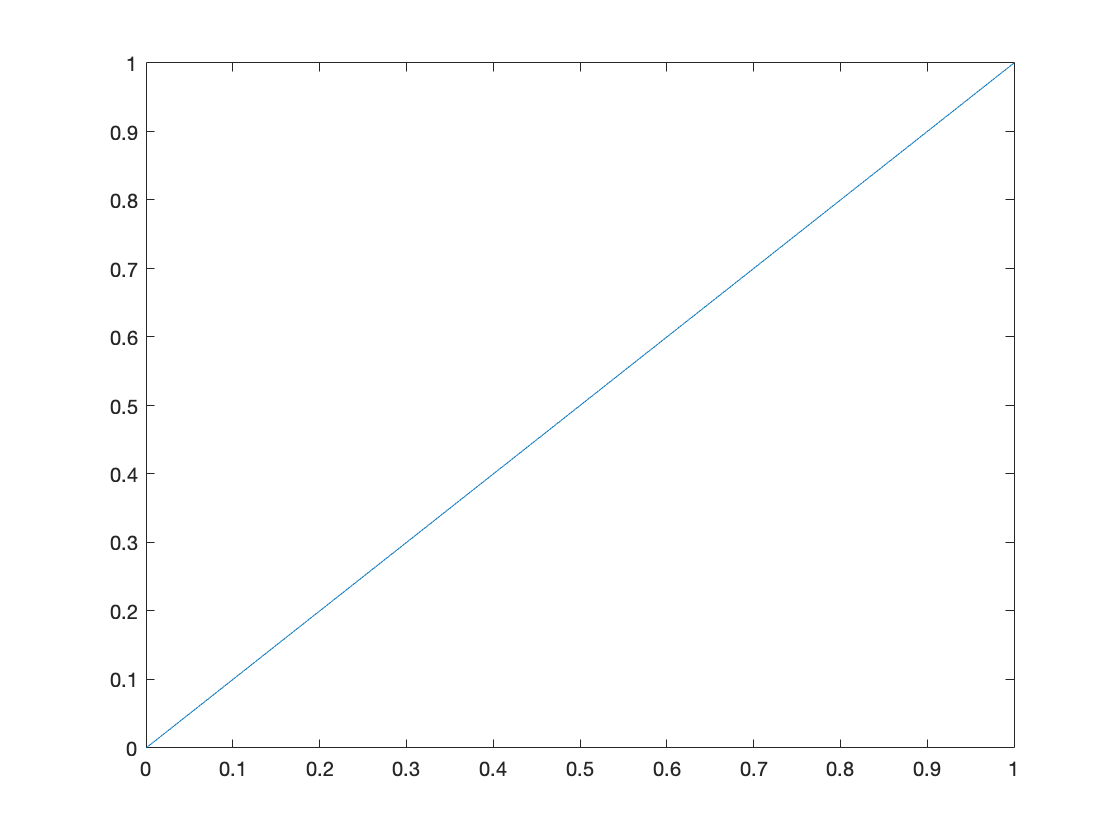

N = 20;
[D,X] = cheb(N);
nu = 1;
D2 = D^2;
u = zeros(length(X),1);
u(1) = 1;
u = u(1:N);
D2 = D2(1:N,1:N);
t = 0;
dt = 1e-3;
u_store = zeros([N+1 1e4+1]);
u_store(1,1) = 1;

t1 = now;
for i = 1:1e4
    t = t + dt;
    u = u + dt * nu * D2/4 * u;
    u(1) = 1;
    u_store(1:N,i+1) = u;
end
u = [u;0];
t2 = now - t1;
% Transform back to known coordinates
p = polyfit(X,u,N);
b = find(abs(p) > 0.1);
p = p(b);
p = p*2; p(2) = 0;
u = polyval(p,(X+1)/2);
plot((X+1)/2,u)

## Define the 1D Diffusion Function

function u = diffuse_cell_x(rhs,u,uL,uR,Fo)

    Nx = u.size(1);
    Ny = u.size(2);
    
    LC = zeros(Ny,Ny);
    for i = 1:Ny
        if i == 1
            LC(i,i) = -3;
            LC(i,i+1) = 1;
        elseif i == Ny
            LC(i,i) = -3;
            LC(i,i-1) = -1;
        else
        LC(i,i) = -2;
        LC(i,i-1) = 1;
        LC(i,i+1) = 1;
        end
    end
    
    u_bc = CellData(Nx,Ny);
    u_bc.x(1,1) = 2*uL - u_bc.x(1,2);
    u_bc.x(1,end) = 2*uR - u_bc.x(1,end-1);
    diff_u_bc = CellData(Nx,Ny);
    for i = 2:Ny+1
        diff_u_bc.x(1,i) = u_bc.x(1,i-1) - 2 * u_bc.x(1,i) + u_bc.x(1,i+1);
    end
    
    rhs.x = rhs.x + 0.5 * Fo * diff_u_bc.x;
    A = eye(Ny) - 0.5 * Fo * LC;
    for j = 1
        B = rhs.x(2:Ny+1);
        a = zeros(length(A)-1,1);
        b = zeros(length(A),1);
        c = zeros(length(A)-1,1);
        for i = 1:length(A)
            if i == 1
                b(i,1) = A(i,i);
                c(i,1) = A(i,i+1);
            elseif i == length(A)
                a(i-1,1) = A(i,i-1);
                b(i,1) = A(i,i);
            else
                a(i-1,1) = A(i,i-1);
                b(i,1) = A(i,i);
                c(i,1) = A(i,i+1);
            end
        end
    end
    
    u.x(2:Ny+1) = trisolve(a,b,c,B,'reg');
    
    u.x(1,1) = 2*uL - u.x(1,2); u.x(1,end) = 2*uR - u.x(1,end-1);
    
end